# Practica 1.

### Alejandro Otero Vázquez y Mario Bravo López

**Tarea 1. **Crea un conjunto de N valores aleatorios que sigan una distribución de probabilidad normal (Gaussiana) y representa conjuntamente su histograma normalizado y la función de densidad de probabilidad teórica que deben seguir los datos. Repetir este procedimiento para los siguientes casos: 

a) Valores de media y desviación típica fijos, μ=0 y σ=1, y distintos valores de N: 

    i. N=100

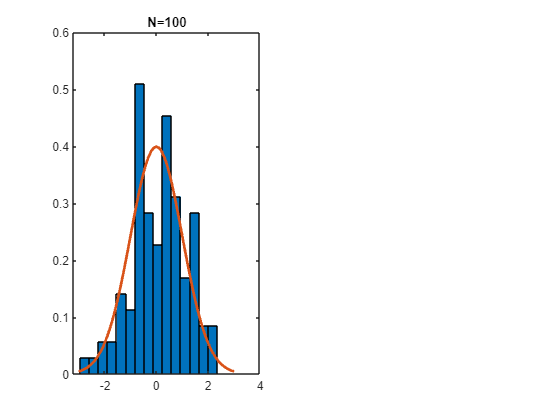

close all;
clear all;

figure(1)

N = 100;
mu = 0;
sigma = 1;

y = mu + sigma*randn(N,1);
[h,xbins] = hist(y,15);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
subplot(1,2,1)
bar(xbins,h_norm,1)

hold on;
v = -3:0.1:3;
pdf = normpdf(v,mu,sigma);
plot(v,pdf,"LineWidth",2)
title('N=100')

   ii. N=5000

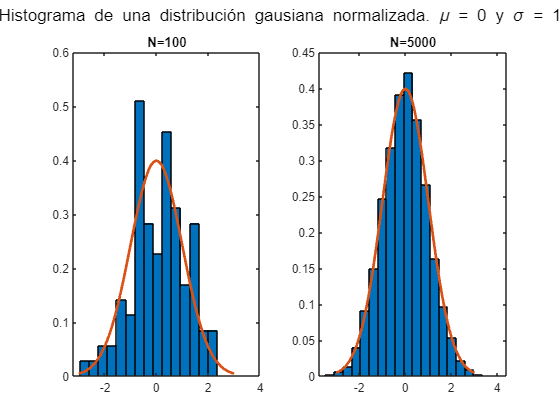


N = 5000;
mu = 0;
sigma = 1;

y = mu + sigma*randn(N,1);
[h,xbins] = hist(y,20);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
subplot(1,2,2)
bar(xbins,h_norm,1)

hold on;
v = -3:0.1:3;
pdf = normpdf(v,mu,sigma);
plot(v,pdf,"LineWidth",2)
title('N=5000')

sgtitle('Histograma de una distribución gausiana normalizada. \mu = 0 y \sigma = 1')

b) Valor N fijo, N=1000, y 3 pares de valores de media y desviación típica distintos: 

    i. μ=-2 y σ=3

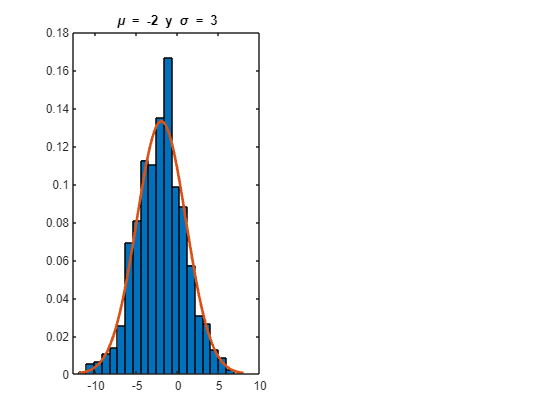

close all;
clear all;

figure(2)

N = 1000;
mu = -2;
sigma = 3;

y = mu + sigma*randn(N,1);
[h,xbins] = hist(y,20);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
subplot(1,2,1)
bar(xbins,h_norm,1)

hold on;
v = -12:0.1:8;
pdf = normpdf(v,mu,sigma);
plot(v,pdf,"LineWidth",2)
title('\mu = -2 y \sigma = 3')

    ii. μ=4 y σ=0.5

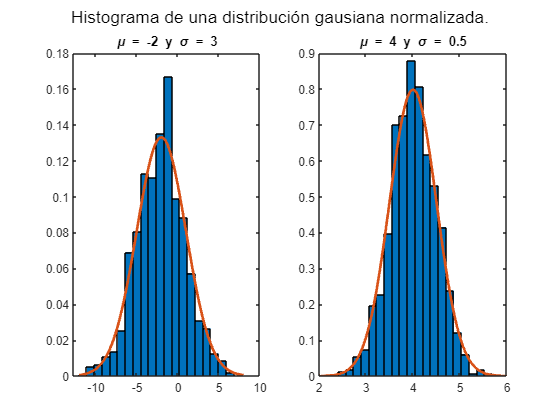

N = 1000;
mu = 4;
sigma = 0.5;

y = mu + sigma*randn(N,1);
[h,xbins] = hist(y,20);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
subplot(1,2,2)
bar(xbins,h_norm,1)

hold on;
v = 2:0.01:6;
pdf = normpdf(v,mu,sigma);
plot(v,pdf,"LineWidth",2)
title('\mu = 4 y \sigma = 0.5')

sgtitle('Histograma de una distribución gausiana normalizada.')

**Tarea 2.** Representa la PDF de los siguientes tipos:

a) Log-normal con μ=0 y σ=1

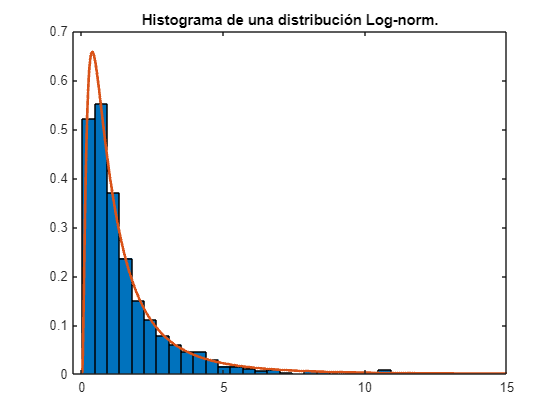

close all;
clear all;

figure(3)

N = 1000;
mu = 0;
sigma = 1;

y=lognrnd(mu,sigma,N,1);

[h,xbins] = hist(y,30);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
bar(xbins,h_norm,1)

hold on;
v = 0:0.01:15;
pdf = lognpdf(v,mu,sigma);
plot(v,pdf,"LineWidth",2)
title('Histograma de una distribución Log-norm.')

b) Student’s T con 3 grados de libertad

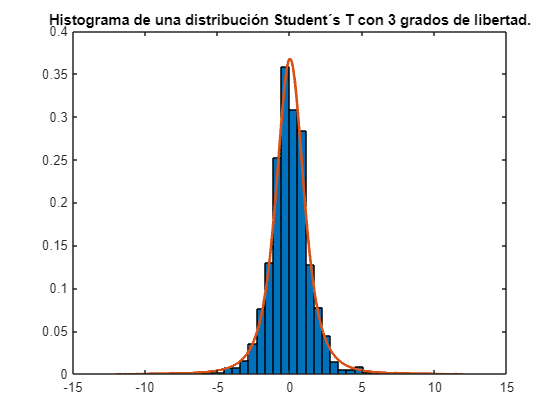

close all;
clear all;

figure(3)

N = 1000;
n = 3;

y=trnd(n,N,1);

[h,xbins] = hist(y,30);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
bar(xbins,h_norm,1)

hold on;
v = -12:0.01:12;
pdf = tpdf(v,n);
plot(v,pdf,"LineWidth",2)
title('Histograma de una distribución Student´s T con 3 grados de libertad.')

c) Rayleigh con β=1

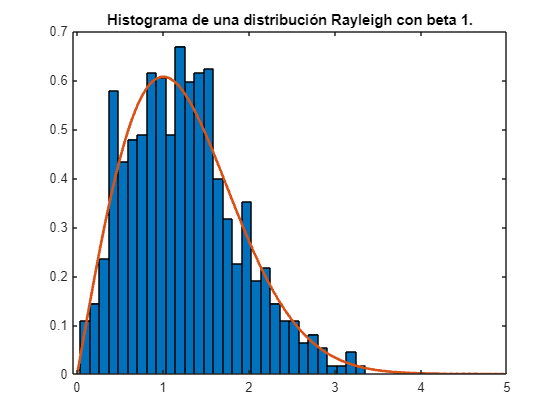

close all;
clear all;

figure(4)

N = 1000;
beta = 1;

y = raylrnd(beta,N,1);

[h,xbins] = hist(y,30);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
bar(xbins,h_norm,1)

hold on;
v = 0:0.01:5;
pdf = raylpdf(v,beta);
plot(v,pdf,"LineWidth",2)
title('Histograma de una distribución Rayleigh con beta 1.')

**Tarea 3.** Crea un conjunto de 1000 valores aleatorios que sigan una PDF de Weibull con parámetro de escala igual a 1 y parámetro de forma igual a 2, y representa conjuntamente su histograma normalizado y la función de densidad de probabilidad teórica que deben seguir los datos. Calcula y representa (sobre el gráfico anterior) la media, la mediana y la moda.

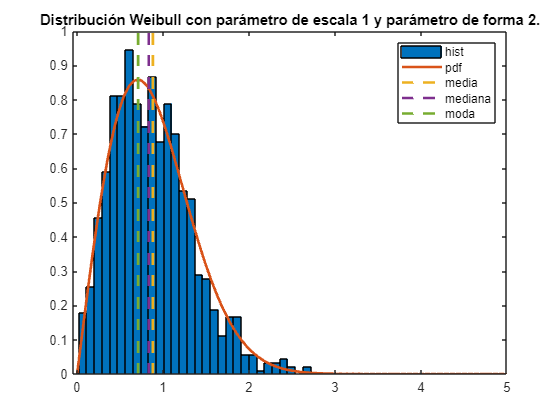

close all;
clear all;

figure(5)

N = 1000;
alpha = 1;
m = 2;
y = wblrnd(alpha,m,N,1);

[h,xbins] = hist(y,30);

bin_width = xbins(2) - xbins(1);
h_norm = h/N/bin_width;
bar(xbins,h_norm,1)

hold on;
v = 0:0.01:5;
pdf = wblpdf(v,alpha,m);
plot(v,pdf,"LineWidth",2)
hold on;
media = mean(y);
mediana = median(y);
[pky,pki] = max(pdf);
moda = v(pki);
line([media, media], ylim, 'LineStyle', '--', 'LineWidth', 2);
line([mediana, mediana], ylim, 'LineStyle', '--', 'LineWidth', 2);
line([moda, moda], ylim, 'LineStyle', '--', 'LineWidth', 2);
legend('hist','pdf','media','mediana','moda');
title('Distribución Weibull con parámetro de escala 1 y parámetro de forma 2.')